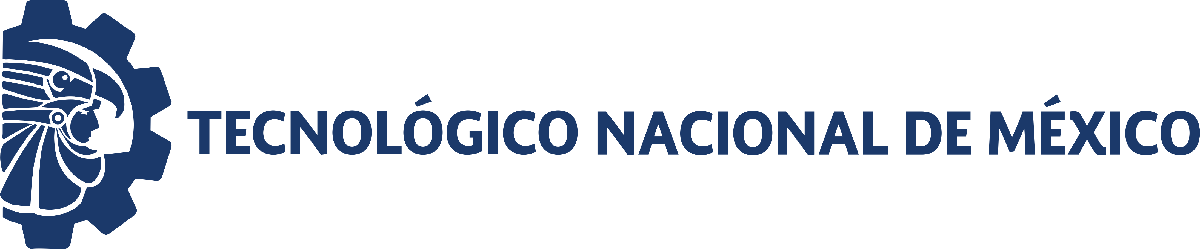                                 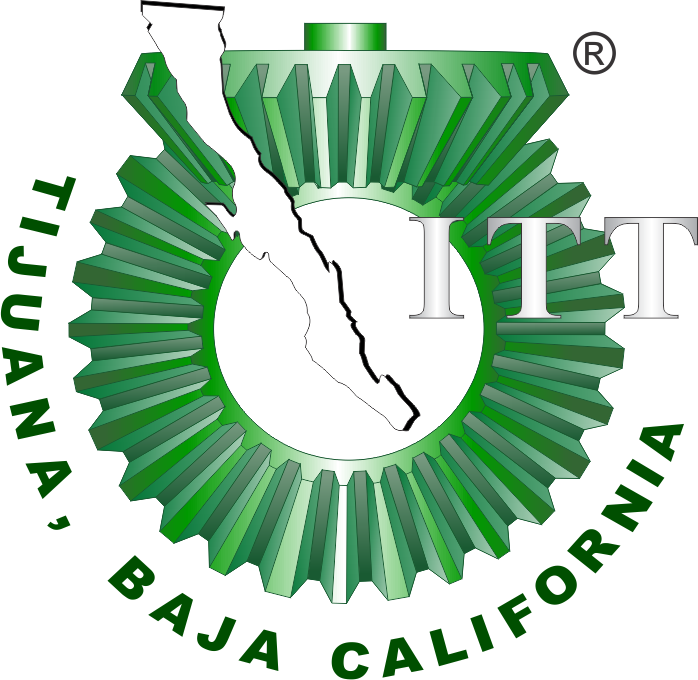

# Práctica 3: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

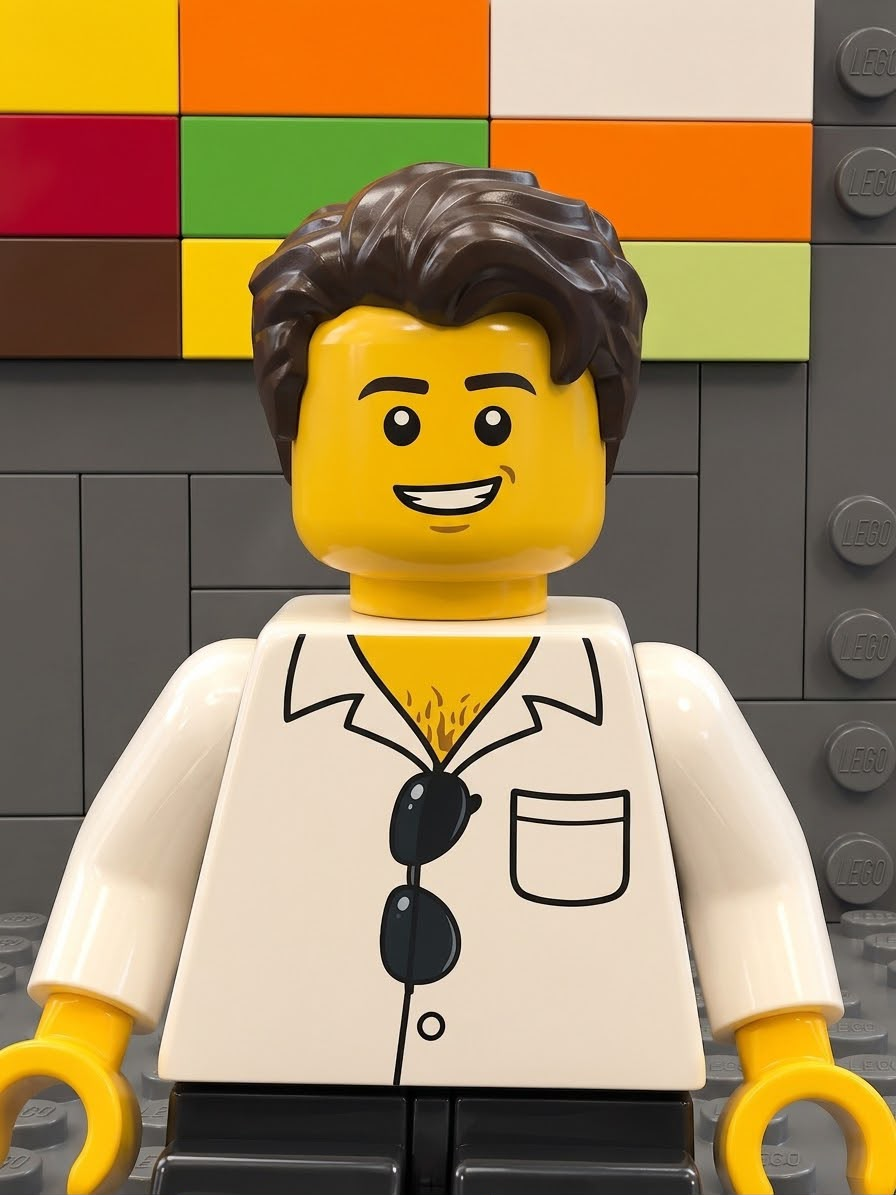

Nombre del alumno: Obregon Maldonado Alan Yahir

Número de control: 23212221

Correo institucional: l23212221**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '11';
file = 'sistema';
open_system(file)
set_param([file '/Step'],'Time','1')   % escalón en t = 1 s
set_param([file '/Scope: Control y Caso'],'DataLogging','on',...
    'DataLoggingVariableName','ScopeData2','DataLoggingSaveFormat','Structure With Time')
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta del sistema: Control y Caso

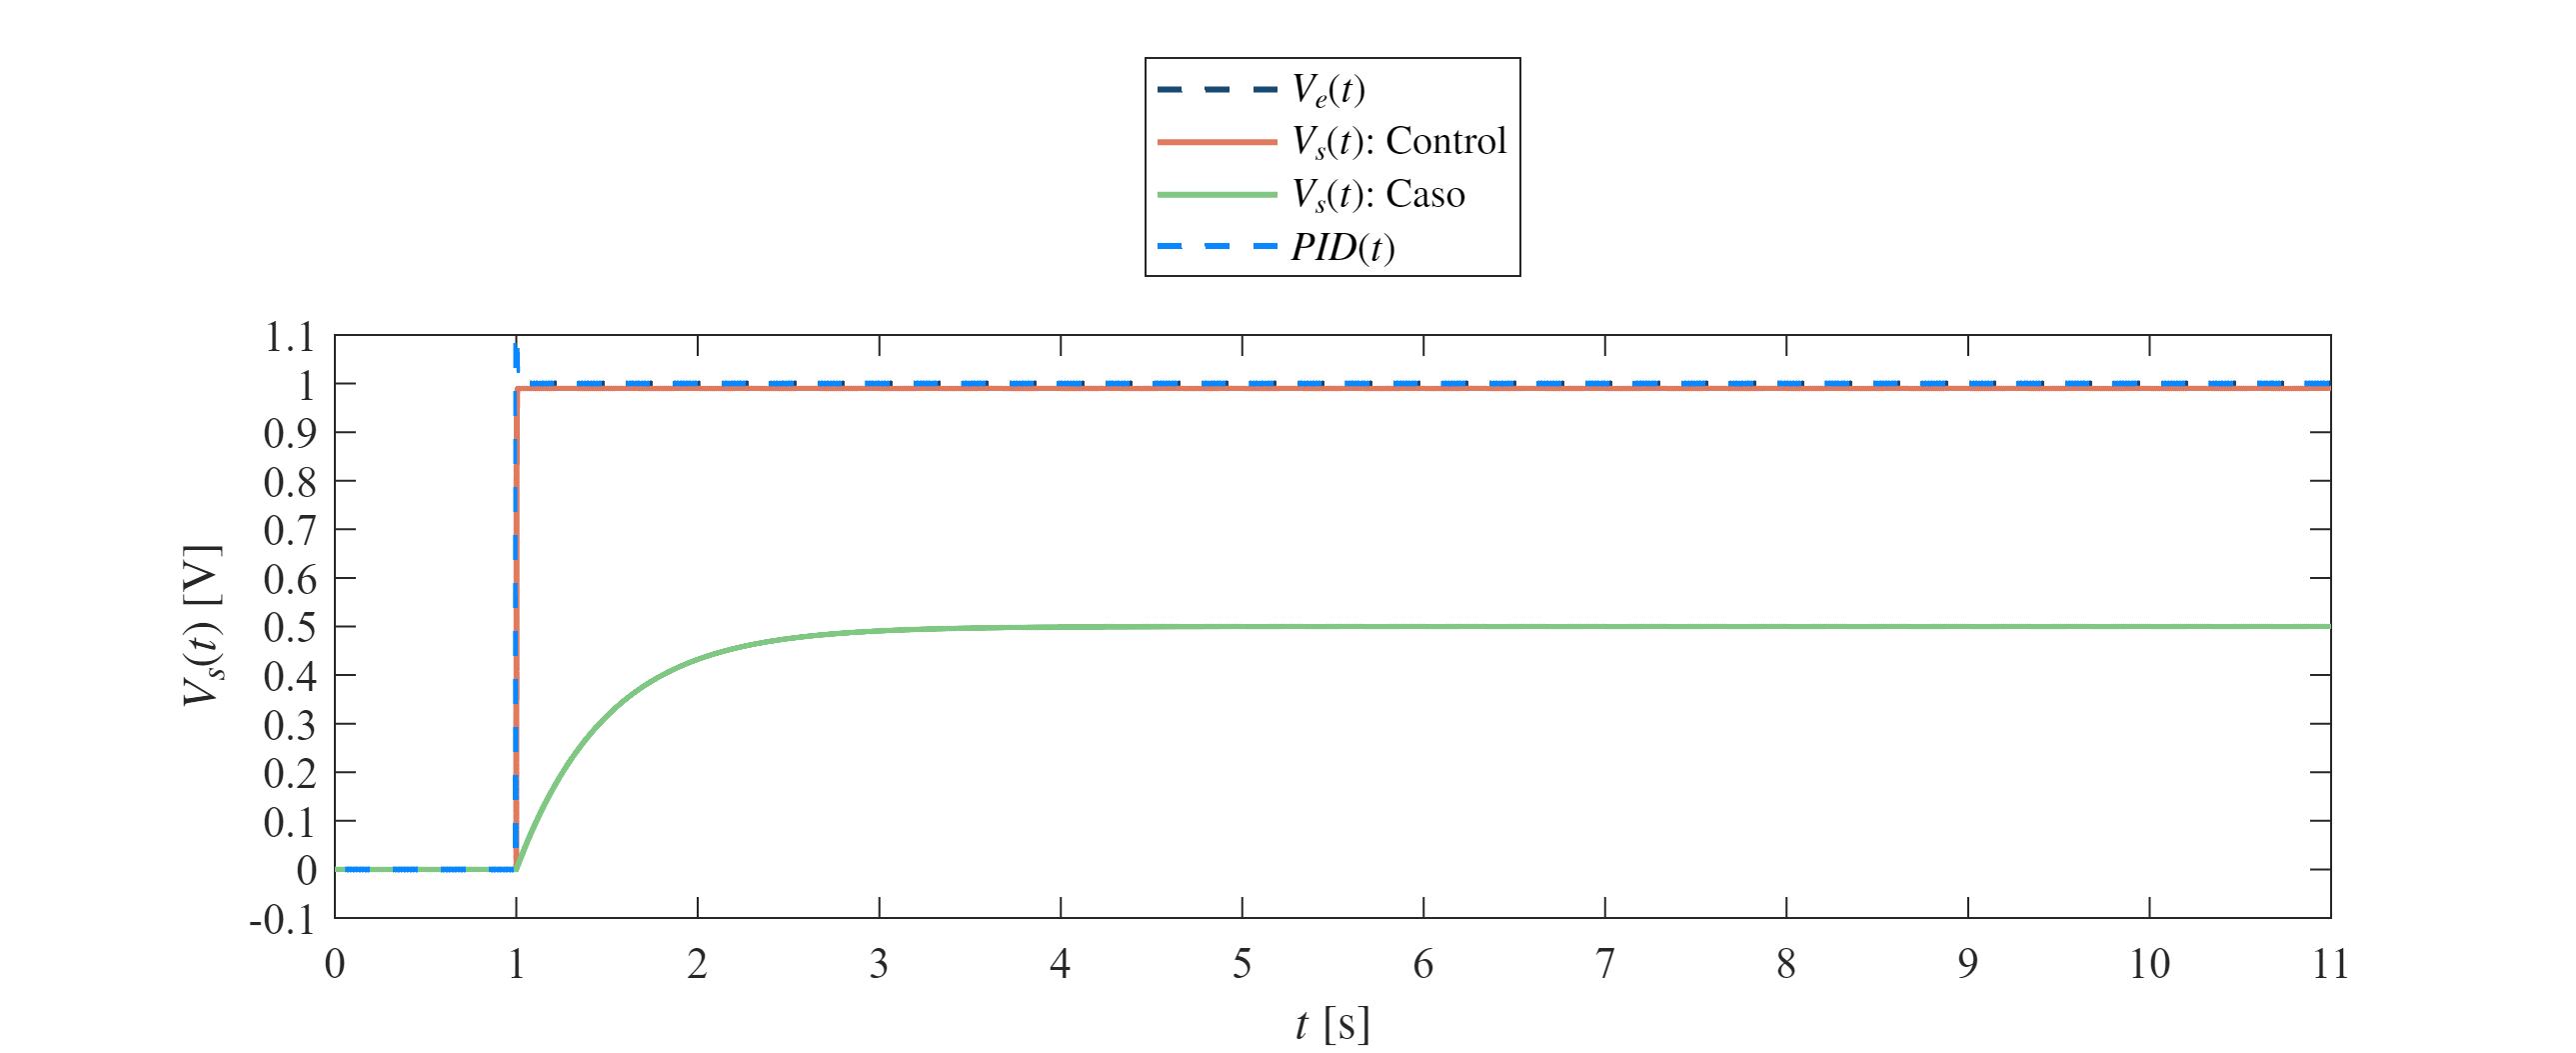

x=sim(file,parameters);
signal = 'Control y caso';
t = x.ScopeData2.time;
V = x.ScopeData2.signals.values;
plotsignals(t,double(t>=1),V(:,1),V(:,4),V(:,7),signal)

## **FUNCION: Respuesta de la simulacion**

function plotsignals(t,s,s1,s2,s3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,11,4.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;

    clr1 = [24, 73, 114]/255;
    clr2 = [224, 122, 95]/255;
    clr3 = [128, 199, 131]/255;
    clr4 = [8, 135, 255]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)


    if signal == "Control y caso"
        plot(t,s,'--',t,s1,'-',t,s2,'-',t,s3,'--', ...
            'LineWidth',1.5,'MarkerSize',5, ...
            'MarkerIndices',1:1e3:length(t));
        l = legend('$V_e(t)$','$V_s(t)$: Control', ...
            '$V_s(t)$: Caso','$PID(t)$');
    end

    set(l,'interpreter','latex','location','northoutside','orientation','vertical')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_s(t)$ [V]','interpreter','latex')

    xlim([0 11]); xticks(0:1:11)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[signal,'.matlab.pdf'],'contentType','vector')
end